Settings

Alles löschen

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

Erstellen symbolische Variablen

syms('R', 'positive')
syms('L', 'positive')
syms('C', 'positive')
syms('C_p', 'positive')
syms('omega', 'positive', 'real')

Numerische Werte

R_num = 6.461;
L_num = 2.724e-3;
C_num = 89.83e-12;
C_p_num = 25.98e-9;


Berechnung Impedanz

Z_RLC = R + 1j * omega * L + 1 / (1j * omega * C);
Z_C_p = 1 / (1j * omega * C_p);
Z_ers = 1/(1/Z_RLC + (1j * omega * C_p))

$$Z\_ers = \frac{1}{C_{p}\,\omega \,\mathrm{i}+\frac{1}{R+L\,\omega \,\mathrm{i}-\frac{\mathrm{i}}{C\,\omega }}}$$

simplify(Z_ers)

$$ans = \frac{-C\,L\,\omega^{2}+\mathrm{i}\,C\,R\,\omega +1}{\omega \,\left(-\mathrm{i}\,C\,C_{p}\,L\,\omega^{2}-C\,C_{p}\,R\,\omega +C\,\mathrm{i}+C_{p}\,\mathrm{i}\right)}$$

Imaginärteil der Ersatz Impedanz

Z_i = imag(Z_ers);

Berechnung der Resonazfrequenzen

Z_i_sol = solve(Z_i == 0, omega, 'ReturnConditions', true)

Z_i_sol = struct with fields:
         omega: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]

omega_rsn = Z_i_sol.omega

$$omega\_rsn = \begin{array}{l} \left(\begin{array}{c} \sqrt{\frac{\sigma_{1}+C\,L+2\,C_{p}\,L-C\,C_{p}\,R^{2}}{2\,C\,C_{p}\,L^{2}}}\\ \sqrt{-\frac{\sigma_{1}-C\,L-2\,C_{p}\,L+C\,C_{p}\,R^{2}}{2\,C\,C_{p}\,L^{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{C}\,\sqrt{-4\,{C_{p}}^{2}\,L\,R^{2}+C\,{C_{p}}^{2}\,R^{4}-2\,C\,C_{p}\,L\,R^{2}+C\,L^{2}} \end{array}$$

f_rsn = omega_rsn / 2 / pi

$$f\_rsn = \begin{array}{l} \left(\begin{array}{c} \frac{\sqrt{\frac{\sigma_{1}+C\,L+2\,C_{p}\,L-C\,C_{p}\,R^{2}}{2\,C\,C_{p}\,L^{2}}}}{2\,\pi }\\ \frac{\sqrt{-\frac{\sigma_{1}-C\,L-2\,C_{p}\,L+C\,C_{p}\,R^{2}}{2\,C\,C_{p}\,L^{2}}}}{2\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{C}\,\sqrt{-4\,{C_{p}}^{2}\,L\,R^{2}+C\,{C_{p}}^{2}\,R^{4}-2\,C\,C_{p}\,L\,R^{2}+C\,L^{2}} \end{array}$$

Bestimmnung der numerischen Werte der Resonanzfrequenzen

omega_rsn_num = subs(omega_rsn, [R, L, C, C_p], [R_num, L_num, C_num, C_p_num]);
omega_rsn_num = double(omega_rsn_num);
omega_rsn_num_1 = omega_rsn_num(1)

omega_rsn_num_1 =      2.0246e+006

omega_rsn_num_2 = omega_rsn_num(2)

omega_rsn_num_2 =      2.0220e+006

Einordnung in Serien und Parallelresonanz

omega_rsn_num_par = omega_rsn_num_1;
Z_rsn_par = (subs(Z_ers, [R, L, C, C_p, omega], [R_num, L_num, C_num, C_p_num, omega_rsn_num_1]));

Impedanz ist hier ein maximuzm, deshalb handelt es sich um eine Parallelresonaz

omega_rsn_num_ser = omega_rsn_num_2;
Z_rsn_ser = (subs(Z_ers, [R, L, C, C_p, omega], [R_num, L_num, C_num, C_p_num, omega_rsn_num_2]));

Impedanz ist hier ein minimun, deshalb handelt es sich um eine Serienresonaz

Frequenzen numerisch:

f_rsn_par = omega_rsn_num_1 / 2 / pi

f_rsn_par =    322.2224e+003

f_rsn_ser = omega_rsn_num_2 / 2 / pi

f_rsn_ser =    321.8145e+003

Numerische Berechnung der Güte bei Serienresonanzfrequnez


$$\[Q = 2\pi \frac{{{E_{\max }}}}{{{P_{\rm{v}}}T}}\]$$


Uq = 1;

Berechnung des Strtoms durch L:

Z_RLC_num  = subs(Z_RLC, [R, L, C, C_p,omega], [R_num, L_num, C_num, C_p_num, omega_rsn_num_ser]);
I_L = Uq / Z_RLC_num;

Spannung an C, Spannung an C_p entspricht uq

U_C = I_L / (1j * omega_rsn_num_ser * C_num);
U_C_p = Uq;

gespeicherte Energie in  L, C, C_p 

E_L = @(t) L_num * abs(I_L)^2 * cos(omega_rsn_num_ser * t + angle(I_L)).^2;
E_C= @(t) C_num * abs(U_C)^2 * cos(omega_rsn_num_ser * t + angle(U_C)).^2;
E_C_p = @(t) C_p_num * abs(U_C_p)^2 * cos(omega_rsn_num_ser * t + angle(U_C_p)).^2;

Bestimment der maximalen Energie mittels fminsearch und inverse der Energie

E_inv = @(t) 1/(E_L(t) + E_C(t) +E_C_p(t));
t_max_E = fminsearch(E_inv,1e-3);
E_max = E_L(t_max_E) + E_C(t_max_E) +E_C_p(t_max_E);
double(E_max)

ans =     56.6094e-006

Berechnung der Verluste

P_v = R_num * abs(I_L) ^2;
double(P_v)

ans =    134.2134e-003

T = 2*pi / omega_rsn_num_ser;
Q_s = double(2 * pi * E_max /(T * P_v))

Q_s =    852.8614e+000

Numerische Berechnung der Güte bei Parallelresonanzfrequenz, gleicher Rechenweg wie bei Parallelresonaz, Berchnung wie bei Serienresonanzfrequnez

Berechnung des Stroms durch L:

Z_RLC_num  = subs(Z_RLC, [R, L, C, C_p,omega], [R_num, L_num, C_num, C_p_num, omega_rsn_num_par]);
I_L = Uq / Z_RLC_num;

Spannung an C, Spannung an C_p entspricht uq

U_C = I_L / (1j * omega_rsn_num_par * C_num);
U_C_p = Uq;

gespeicherte Energie in  L, C, C_p 

E_L = @(t) L_num * abs(I_L)^2 * cos(omega_rsn_num_par * t + angle(I_L)).^2;
E_C= @(t) C_num * abs(U_C)^2 * cos(omega_rsn_num_par * t + angle(U_C)).^2;
E_C_p = @(t) C_p_num * abs(U_C_p)^2 * cos(omega_rsn_num_par * t + angle(U_C_p)).^2;

Bestimment der maximalen Energie mittels fminsearch und inverse der Energie

E_inv = @(t) 1/(E_L(t) + E_C(t) +E_C_p(t));
t_max_E = fminsearch(E_inv,1e-3);
E_max = E_L(t_max_E) + E_C(t_max_E) +E_C_p(t_max_E);
double(E_max)

ans =      8.7043e-006

Berechnung der Verluste

P_v = R_num * abs(I_L) ^2;
double(P_v)

ans =     20.6231e-003

T = 2*pi / omega_rsn_num_par;
Q_p = double(2 * pi * E_max /(T * P_v))

Q_p =    854.5084e+000

Bandbreite

Um die Rechenzeit für die numerische Ermittlung der Bandbreite zu reduzieren ist es vorteilhaft das Suchintervall einzuschränken, dafür wird eine grafische Darstellung verwendet

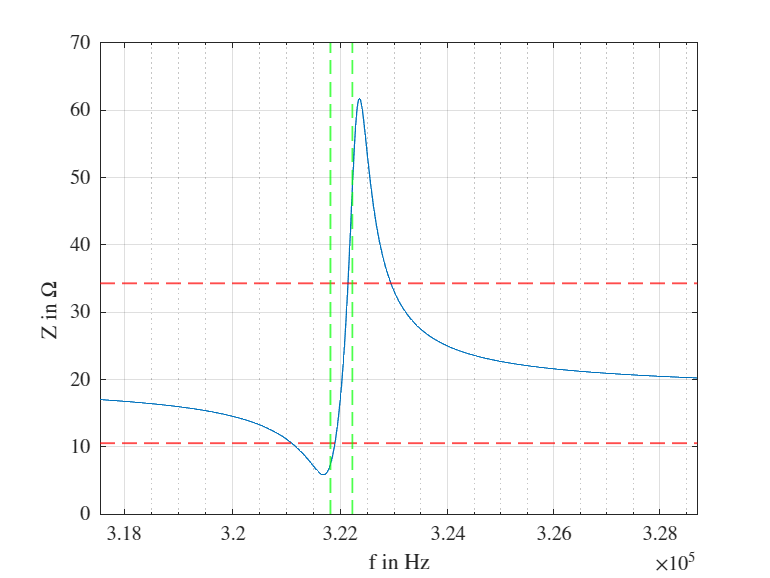

omega_b = logspace(6.3, 6.315, 1001);
Z_b = 1 ./ ((1j * omega_b * C_p_num) + 1 ./ ((1j * omega_b * L_num) + R_num + 1 ./ (1j * omega_b * C_num)));
Z_b = double(abs(Z_b));
Schranke_par = double(abs(Z_rsn_par * 1/ sqrt(2)));
Schranke_ser = double(abs(Z_rsn_ser * sqrt(2)));

figure
semilogx(omega_b/(2*pi), Z_b) 
hold on
yline(Schranke_par, '--r', 'LineWidth', 1); % Dashed red line
yline(Schranke_ser, '--r', 'LineWidth', 1); % Dashed red line
xline(omega_rsn_num_ser/ 2 / pi, '--g','LineWidth', 1)
xline(omega_rsn_num_par / 2 / pi, '--g','LineWidth', 1)
hold off
xlabel('f in Hz')
ylabel('Z in $\Omega$')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom')
grid('on')

Durch die grafische Darstellung ist erkennbar, das die relevanten Intervalle ür Serienresonaz zwischen 3.2e5 und 3.225e5 Hz liegen.

 Es werden jene Frequenzen gesucht an denen die Impedanz gleich der Wurzel 2 mal der Impedanz bei Serienresonanz ist

  $Z({\omega _{\rm, go, gu}) - \sqrt 2 Z({\omega _{\rm rsn}}) = 0$.

Z_sol_s = @(omega) abs(1 ./ ((1j * omega * C_p_num) + 1 ./ ((1j * omega * L_num) + R_num + 1 ./ (1j * omega * C_num)))) - sqrt(2) * abs(double(real(Z_rsn_ser)));

Berechnung der unteren und oberen Halbleistungsfrequenzen für Serienresonanz 

omega_gu_s = double(fzero(Z_sol_s, [2e6, omega_rsn_num_ser]))

omega_gu_s =      2.0175e+006

omega_go_s = double(fzero(Z_sol_s, [omega_rsn_num_ser, 2.05e6]))

omega_go_s =      2.0225e+006

Durch die grafische Darstellung ist erkennbar, das die relevanten Intervalle für Parallelresonaz zwischen 3.22e5 und 3.225e5 Hz liegen.

  $Z({\omega _{\rm, go, gu}) - \frac{1}{\sqrt 2} Z({\omega _{\rm rsn}}) = 0$.

Z_sol_s = @(omega) abs(1 ./ ((1j * omega * C_p_num) + 1 ./ ((1j * omega * L_num) + R_num + 1 ./ (1j * omega * C_num)))) - 1/sqrt(2) * abs(double(real(Z_rsn_par)));

Berechnung der unteren und oberen Halbleistungsfrequenzen für Parallelresonanz 

omega_gu_p = double(fzero(Z_sol_s, [2.02e6, omega_rsn_num_par]))

omega_gu_p =      2.0241e+006

omega_go_p = double(fzero(Z_sol_s, [omega_rsn_num_par, 2.35e6]))

omega_go_p =      2.0291e+006

Berechnung der Bandbreite

B_s =( omega_go_s - omega_gu_s) / 2 / pi

B_s =    800.7246e+000

B_p = (omega_go_p - omega_gu_p) / 2 / pi

B_p =    800.7372e+000

Speichern der Daten

save('Aufgabe1')